# Demo: A-units are redundant

Script to demonstrate that a layer of linear units in Rosenblatt's simple perceptron is redundant because it can be summarized in just one vector of weights.

Assignments don't end with semicolon, so you can see the result of each operation. Values are generated at random and the threshold is 0, since we are not interested in the numerical results but only in showing that the result itself is the same with and without the A-units.

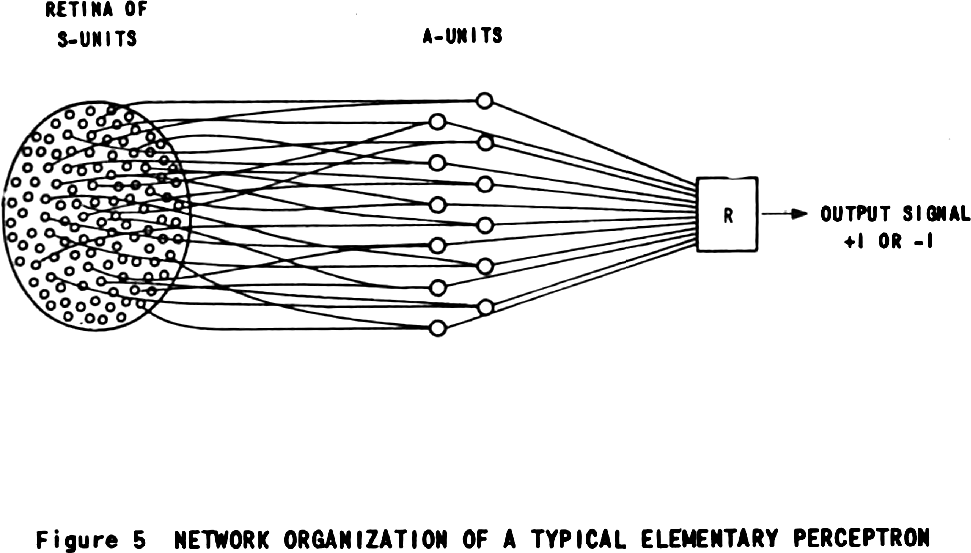

**Generate** a random 2-dimensional matrix of 1 observation with values in [-1,1]:

x = 2*rand(1,2)-1

x =    -0.8396   -0.1724


**Generate** random weights for 4 A-units as a matrix with 4 columns.

Columns are 2-dimensional because they have to multiply the 2-dimensional observation

Wa = 2*rand(2,4)-1

Wa =    -0.6383    0.0408    0.2965   -0.8094
    0.9913    0.7706   -0.0675    0.9356


**Generate** random weights for 1 R-unit as a matrix with 1 column.

The column is 4-dimensional because it has to multiply the vector of 4 outputs from the 4 A-units.

Wr = 2*rand(4,1)-1

Wr =     0.2402
   -0.6880
   -0.2033
    0.7650


**Calculate** the output of the A-units. There is no activation function, so no nonlinear part.

a1 = x(1,:)*Wa  % (1)

a1 =     0.3651   -0.1670   -0.2373    0.5184


**Calculate **the output of the r-units. Linear part (r1):

r1 = a1*Wr      % (2)

r1 = 0.6474

Nonlinear activation to compute y1:

y1 = f(r1)

y1 = 1

r1 and y1 are the outputs of the linear and nonlinear blocks, respectively, of the r-unit in the first case.

### ALTERNATIVE

Now let's do the same by collapsing the weights into one weight vector W. Performing (1) and (2) in cascade is equivalent to doing the following:

W = Wa*Wr

W =    -0.8609
    0.4375


r2 = x(1,:)*W

r2 = 0.6474

Now we have r2 directly and we can **compute** the corresponding output y2:

y2 = f(r2)

y2 = 1

Let's **check** if the result is the same

fprintf("r1 and r2 are the same: %s\n",mat2str(abs(r1-r2)<1e-15)); % comparing floating point numbers with a tolerance

r1 and r2 are the same: true



fprintf("y1 and y2 are the same: %s\n",mat2str(y1==y2));

y1 and y2 are the same: true


This shows that a linear A-layer with weights Wa can be collapsed into the weights Wr of the nonlinear R-unit and achieve the same result as a R-unit with weights W. So linear layers are redundant.

function a = f(r)
% This is the activation function - the signum function with threshold 0
  theta = 0;
  a = 2*double(r>theta)-1;
end
